clear all;
PS = PLOT_STANDARDS();

close all

g = 9.81

g = 9.8100

V_Take_off = 10 

V_Take_off = 10

S_Take_off = 60

S_Take_off = 60

Climb_angle = deg2rad(10)

Climb_angle = 0.1745

V_climb = 17.6 

V_climb = 17.6000

S_climb = 1417 

S_climb = 1417

V_cruise = 17

V_cruise = 17

S_cruise = 20000

S_cruise = 20000

V_des_1 = 20.52

V_des_1 = 20.5200

S_des_1 = 567

S_des_1 = 567

V_loiter = 20.52

V_loiter = 20.5200

S_loiter = 10000

S_loiter = 10000

V_des_2 = 10.83

V_des_2 = 10.8300

S_des_2 = 850

S_des_2 = 850

Descent_angle = deg2rad(10)

Descent_angle = 0.1745

V_land = 8.61 

V_land = 8.6100

S_land = 80 

S_land = 80




energy_density = 2200*12*3.6/0.4

energy_density = 237600

id = '1fLRThdq1Lwjppod5IEgEVGaNP7Vt-bhdvqtFt6ZVha8'

id = '1fLRThdq1Lwjppod5IEgEVGaNP7Vt-bhdvqtFt6ZVha8'

sheet_name = 'Historic_data'

sheet_name = 'Historic_data'

url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s', id, sheet_name);
Data = webread(url_name)

Data = 12×24 table
    SlNo           UAVName           MTOWKg    EmptyWeightKg    BatteryWeightKg    PayloadWeightKg    RangeKm    EnduranceMinutes    ServiceCeilingM    MaximumCeilingM    CruiseSpeedKm_hr    MaxSpeedKm_hr    LongitudinalLengthCm    WingSpanCm    ReferenceWingAreaCm2    WettedWingArea    AR     BatteryCapacity_PowerAmpereHour    BatteryVoltageVolts          L_D           T_W    NetThrustKgf    ThrustPerMotorKgf                                                                             Reference                                                                         


C_d_0 = 0.03

C_d_0 = 0.0300

e = 0.7

e = 0.7000

AR = 6

AR = 6

S = 0.7

S = 0.7000

AR = (mean(0.01*table2array(Data(1:7,"WingSpanCm"))))^2/S

AR = 8.1309

rho = 1.225

rho = 1.2250

t_climb = S_climb/(V_climb*cos(Climb_angle))

t_climb = 81.7534

t_cruise = S_cruise/V_cruise

t_cruise = 1.1765e+03

t_des_1 = S_des_1/(V_des_1*cos(Descent_angle))

t_des_1 = 28.0578

t_loiter = S_loiter/V_loiter

t_loiter = 487.3294

t_des_2 = S_des_2/(V_des_2*cos(Descent_angle))

t_des_2 = 79.6965

t_total = t_climb + t_cruise + t_des_1 + t_loiter + t_des_2

t_total = 1.8533e+03

t_total_min = t_total/60

t_total_min = 30.8885

Empty Weight fraction

Mtow_data = table2array(Data(1:7,"MTOWKg"))

Mtow_data =     4.5000
   10.0000
    9.0000
    5.0000
    5.0000
    9.5000
    7.5000


Empty_weight_data = table2array(Data(1:7,"EmptyWeightKg"))

Empty_weight_data =     2.3870
    3.5000
    2.5000
    3.0000
    3.4000
    4.5000
    5.5000



Empty_weight_frac_data = Empty_weight_data./Mtow_data;

fit_1 = fit(Mtow_data,Empty_weight_frac_data,'power1');

A_1 = fit_1.a;
C_1 = fit_1.b;


figure(1)
fig_comps.fig = gcf;
hold on 
fig_comps.p1 = plot(linspace(min(Mtow_data),max(Mtow_data),1000),fit_1(linspace(min(Mtow_data),max(Mtow_data),1000)),'Displayname','Fitted Curve')

fig_comps = struct with fields:
    fig: [1×1 Figure]
     p1: [1×1 Line]
     p2: [1×1 Line]


fig_comps.p2 = plot(Mtow_data,Empty_weight_frac_data,'Marker','o','Markersize',5,'LineStyle','none','MarkerFaceColor','auto','MarkerEdgeColor','auto','DisplayName','Historical Data')

fig_comps = struct with fields:
    fig: [1×1 Figure]
     p1: [1×1 Line]
     p2: [1×1 Line]


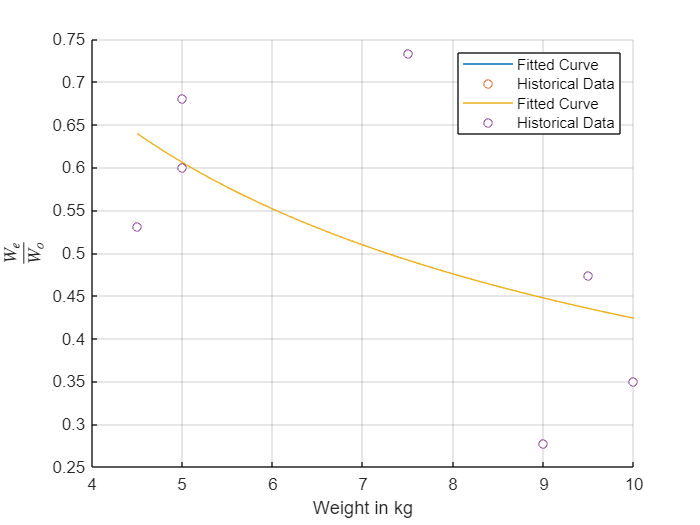

legend()
xlabel('Weight in kg')
ylabel('$$ \frac{W_{e}}{W_{o}} $$','Interpreter','latex')
grid on 

Battery weight first estimation

Power_required_cruise = @(W,V) 0.5*rho*V^3*S*C_d_0 + 2*W^2/(rho*V*S*pi*e*AR)

Power_required_cruise = function_handle with value:
    @(W,V)0.5*rho*V^3*S*C_d_0+2*W^2/(rho*V*S*pi*e*AR)


Power_required_climb = @(W,V,theta) W*V*sin(theta) + Power_required_cruise(W,V)

Power_required_climb = function_handle with value:
    @(W,V,theta)W*V*sin(theta)+Power_required_cruise(W,V)


Power_required_descent = @(W,V,theta) Power_required_cruise(W,V) - V*sin(theta)*W

Power_required_descent = function_handle with value:
    @(W,V,theta)Power_required_cruise(W,V)-V*sin(theta)*W


Total_power_required = @(W) Power_required_climb(W,V_climb,Climb_angle)*t_climb ...
    + Power_required_cruise(W,V_cruise)*t_cruise ...
    + Power_required_cruise(W,V_loiter)*t_loiter 

Total_power_required = function_handle with value:
    @(W)Power_required_climb(W,V_climb,Climb_angle)*t_climb+Power_required_cruise(W,V_cruise)*t_cruise+Power_required_cruise(W,V_loiter)*t_loiter



% Power_required_descent(100,V_des_1,Descent_angle)/energy_density

W_payload = 1.4

W_payload = 1.4000

W_initial = 5.6000

W_initial = 4*W_payload
W_0 = W_initial

W_0 = 5.6000

Weight_count = [W_initial]

Weight_count = 5.6000

for i = 1:1:15
    W_new = W_payload/(1 - fit_1(W_0) - Total_power_required(W_0*g)/(energy_density*W_0));
    c = fit_1(W_0) ; %+ Total_power_required(W_0*g)/(energy_density*W_0);
    W_0 = 0.5*W_0 + 0.5*W_new;
    Weight_count = [Weight_count W_0];
end

Weight_count

Weight_count =     5.6000    5.2265    5.2799    5.2674    5.2702    5.2695    5.2697    5.2697    5.2697    5.2697    5.2697    5.2697    5.2697    5.2697    5.2697    5.2697


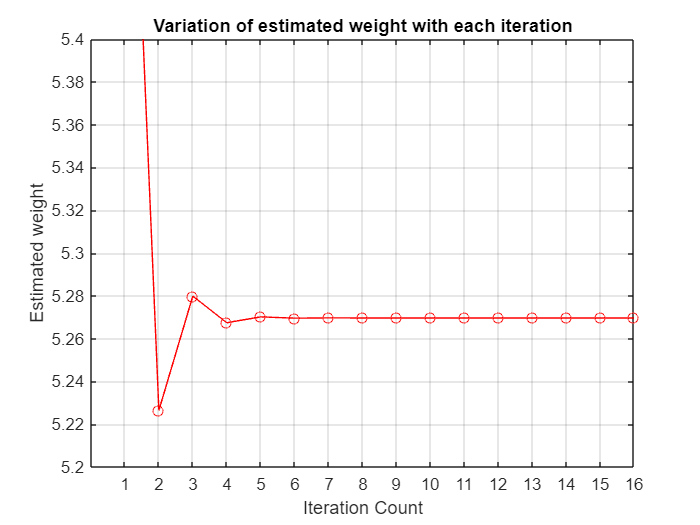


figure(2)
plot(Weight_count,'-o',Color='red')
xticks([1:16])
ylim([5.2,5.4])
grid on 
xlabel('Iteration Count')
ylabel('Estimated weight')
title('Variation of estimated weight with each iteration')
saveas(gcf,'weight.png')